1 c)

%define A matrix and mu_q sigma_q
A = [1,0.5;0,1];
mu_q = [0;10];
sigma_q = [0.3,0;0,8];
%calculate mu_z sigma_z with the equations in b)
mu_z = A*mu_q;
sigma_z = A*sigma_q*A'

sigma_z =     2.3000    4.0000
    4.0000    8.0000




%draw the ellipse
[ xy_q ] = sigmaEllipse2D( mu_q, sigma_q);
[ xy_z ] = sigmaEllipse2D( mu_z, sigma_z );


%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure('Position',[300 300 600 400]);
h1 = plot(xy_q(1,:), xy_q(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
plot(mu_q(1), mu_q(2), '*', 'color', h1.Color);
xlabel('q1') % Set x-axis label
ylabel('q2') % Set y-axis label
legend('Covariance contour ellipse for q','expectation for q','Location','southeast') % Dont forget to add a legend. You can change its location by changing 'southeast'.
grid on ;
hold off

figure('Position',[300 300 600 400]);
h2 = plot(xy_z(1,:), xy_z(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
plot(mu_z(1), mu_z(2), '*', 'color', h1.Color);
xlabel('z1') % Set x-axis label
ylabel('z2') % Set y-axis label
legend('Covariance contour ellipse for z','expectation for z','Location','southeast') % Dont forget to add a legend. You can change its location by changing 'southeast'.
grid on ;
hold off

2 a)

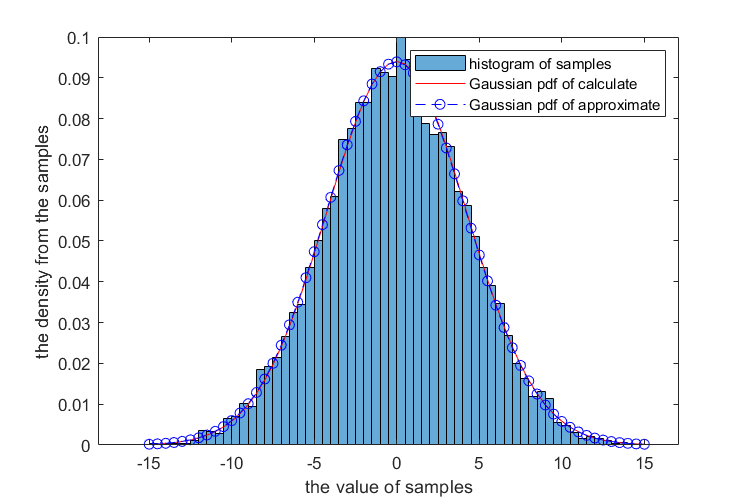


%the original distribution
mu_x = 0;
Sigma_x = 2;

%get the distribution analytically
mu_za = 3*mu_x ;
sigma_za = 9*Sigma_x;

%get the distribution numerically
f = @(x)(3*x);
N = 10000;
[mu_zn, sigma_zn, z_s] = approxGaussianTransform(mu_x, Sigma_x, f, N);

x_za=[-15:0.5:15];
y_za = normpdf(x_za,mu_za,sqrt(sigma_za));
x_zn=[-15:0.5:15];
y_zn = normpdf(x_zn,mu_zn,sqrt(sigma_zn));

figure('Position',[300 300 600 400]);
h1 = histogram(z_s,'Normalization','pdf');
xlabel('the value of samples') % Set x-axis label
ylabel('the density from the samples') % Set y-axis label
hold on
plot(x_za,y_za,'r');
hold on
plot(x_zn,y_zn,'b--o');
legend('histogram of samples','Gaussian pdf of calculate','Gaussian pdf of approximate','Location','northeast')
hold off

2 b)

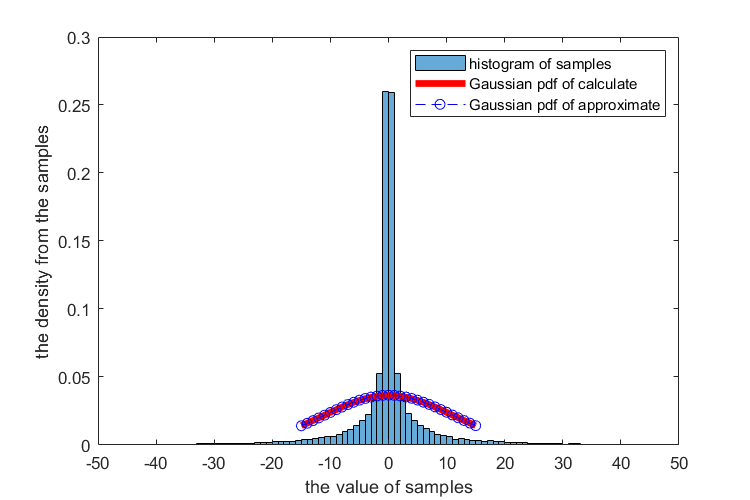


%the original distribution
mu_x = 0;
Sigma_x = 2;

%get the distribution analytically
mu_za = 0;
sigma_za =120;

%get the distribution numerically
f = @(x)(x^3);
N = 100000;
[mu_zn, sigma_zn, z_s] = approxGaussianTransform(mu_x, Sigma_x, f, N);

x_za=[-15:1:15];
y_za = normpdf(x_za,mu_za,sqrt(sigma_za));
x_zn=[-15:1:15];
y_zn = normpdf(x_zn,mu_zn,sqrt(sigma_zn));

figure('Position',[300 300 600 400]);
h1 = histogram(z_s,'Normalization','pdf');
xlabel('the value of samples') % Set x-axis label
ylabel('the density from the samples') % Set y-axis label
hold on
plot(x_za,y_za,'LineWidth',4,'color','r');
hold on
plot(x_zn,y_zn,'b--o');
xlim([-50 50]) % Adjust the xaxis if needed.
legend('histogram of samples','Gaussian pdf of calculate','Gaussian pdf of approximate','Location','northeast')
hold off

3 e)

%nonlinear function
f_nl =  @(x)(x^3);
%linear function
f_l =  @(x)(6*x);
%number of sample
N = 100000;

%x_su for a sample x fron uniform distribution
x_su = 3+(9-3)*rand(1,N);
x_sn = (mvnrnd(1,4,N))';
r_s = (mvnrnd(0,9,N))';


%% calculate p(y) numerically
%linear function with x_su
y_us_l=[];
for i= 1:N
    ys = r_s(:,i) + f_l(x_su(:,i));
    y_us_l = [y_us_l,ys];
end 


%nonlinear function with x_su
y_us_nl=[];
for i= 1:N
    ys = r_s(:,i) + f_nl(x_su(:,i));
    y_us_nl = [y_us_nl,ys];
end


%linear function with x_sn
y_ns_l=[];
for i= 1:N
    ys = r_s(:,i) + f_l(x_sn(:,i));
    y_ns_l = [y_ns_l,ys];
end 
%nonlinear function with x_sn
y_ns_nl=[];
for i= 1:N
    ys = r_s(:,i) + f_nl(x_sn(:,i));
    y_ns_nl = [y_ns_nl,ys];
end




%% calculate p(y|x) numerically
%define x
xs=50+(60-50)*rand;

%linear function
yx_s_l=[];
for i= 1:N
    ys = r_s(:,i) + f_l(xs);
    yx_s_l = [yx_s_l,ys];
end 
%nonlinear function
yx_s_nl=[];
for i= 1:N
    ys = r_s(:,i) + f_nl(xs);
    yx_s_nl = [yx_s_nl,ys];
end



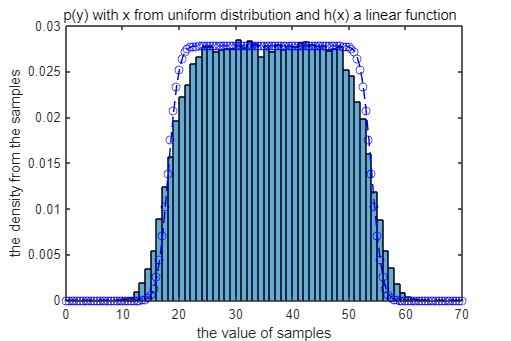

%%calculate 


figure('Position',[300 300 600 400]);
%numerically
h1 = histogram(y_us_l,'Normalization','pdf');
xlabel('the value of samples') % Set x-axis label
ylabel('the density from the samples') % Set y-axis label
title('p(y) with x from uniform distribution and h(x) a linear function  ')
hold on

%analytically
y=[0:0.5:70];
p_y = (erf((y-18)/3*sqrt(2))-erf((y-54)/3*sqrt(2)))/72;
plot(y,p_y,'b--o');
hold off


figure('Position',[300 300 600 400]);
h2 = histogram(y_us_nl,'Normalization','pdf');
xlabel('the value of samples') % Set x-axis label
ylabel('the density from the samples') % Set y-axis label
title('p(y) with x from uniform distribution and h(x) a nonlinear function  ')

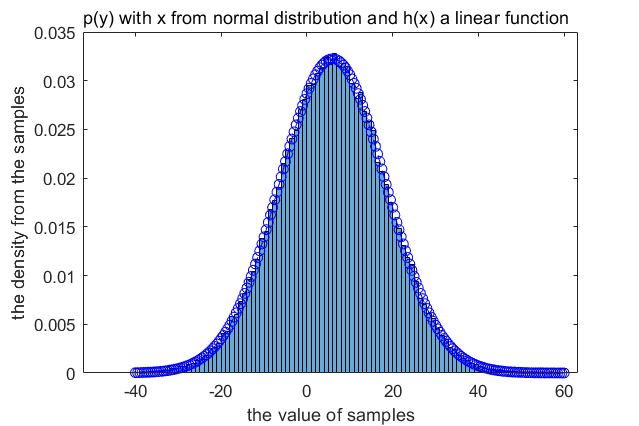


figure('Position',[300 300 600 400]);
%numerically
h3 = histogram(y_ns_l,'Normalization','pdf');
xlabel('the value of samples') % Set x-axis label
ylabel('the density from the samples') % Set y-axis label
hold on
%analytically
mu = 6*1;
sigma = 36*4+9;
x=[-40:0.5:60];
y = normpdf(x,mu,sqrt(sigma));
plot(x,y,'b--o');
hold off
title('p(y) with x from normal distribution and h(x) a linear function  ')

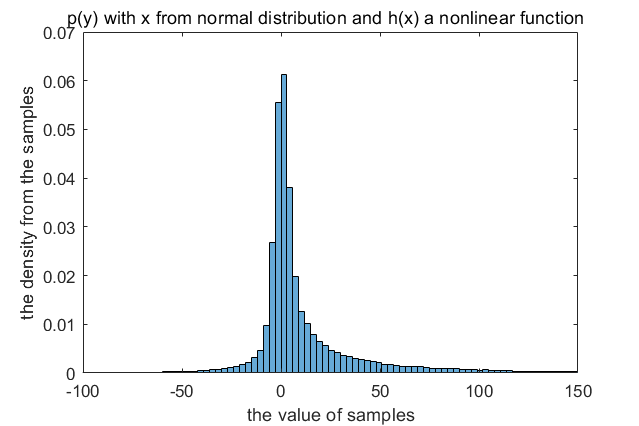



figure('Position',[300 300 600 400]);
h4 = histogram(y_ns_nl,'Normalization','pdf');
xlabel('the value of samples') % Set x-axis label
ylabel('the density from the samples') % Set y-axis label
xlim([-100 150]) % Adjust the xaxis if needed.
title('p(y) with x from normal distribution and h(x) a nonlinear function  ')

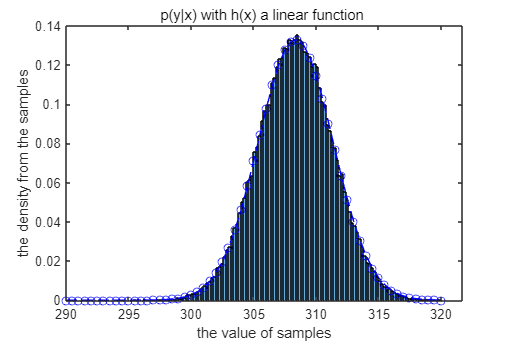


figure('Position',[300 300 600 400]);
h5 = histogram(yx_s_l,'Normalization','pdf');
xlabel('the value of samples') % Set x-axis label
ylabel('the density from the samples') % Set y-axis label
hold on
%analytically
mu = 6*xs;
sigma = 9;
x=[290:0.5:320];
y = normpdf(x,mu,sqrt(sigma));
plot(x,y,'b--o');
hold off
title('p(y|x) with h(x) a linear function ')

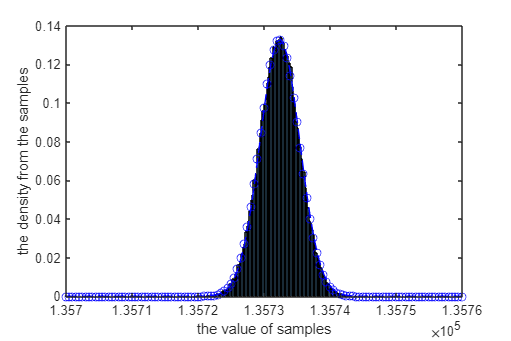


figure('Position',[300 300 600 400]);
h6 = histogram(yx_s_nl,'Normalization','pdf');
xlabel('the value of samples') % Set x-axis label
ylabel('the density from the samples') % Set y-axis label
hold on
%analytically
mu = xs^3;
sigma = 9;
x=[135700:0.5:135760];
y = normpdf(x,mu,sqrt(sigma));
plot(x,y,'b--o');
hold off

% title('p(y|x) with h(x) a nonlinear function ')





4 a)

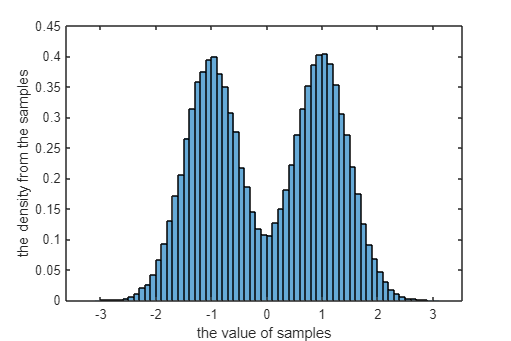

N=100000;

theta_s=[];
for i=1:N
    
    if rand >= 0.5
        theta = 1;
    else
        theta = (-1);
    end
    theta_s=[theta_s,theta];
end
    
w_s = (mvnrnd(0,0.25,N))';

y_s=[];
for i =1:N
    y = theta_s(:,i)+ w_s(:,i);
    y_s=[y_s,y];
end

figure('Position',[300 300 600 400]);
h6 = histogram(y_s,'Normalization','pdf');
xlabel('the value of samples') % Set x-axis label
ylabel('the density from the samples') % Set y-axis label

4 f)

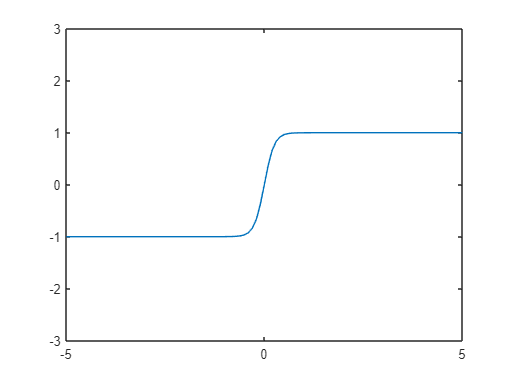

sigma_w = 0.5;
y=[-20:0.1:20];
p= tanh(y/(sigma_w)^2);
figure;
plot(y,p);
xlim([-5 5]) % Adjust the xaxis if needed.
ylim([-3 3]) % Adjust the yaxis if needed.

Functions might used

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, npoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
%   MU          [2 x 1] Mean of the Gaussian density
%   SIGMA       [2 x 2] Covariance matrix of the Gaussian density
%   LEVEL       Which sigma level curve to plot. Can take any positive value, 
%               but common choices are 1, 2 or 3. Default = 3.
%   NPOINTS     Number of points on the ellipse to generate. Default = 32.
%
%Output:
%   XY          [2 x npoints] matrix. First row holds x-coordinates, second
%               row holds the y-coordinates. First and last columns should 
%               be the same point, to create a closed curve.
%Setting default values, in case only mu and Sigma are specified.
if nargin < 3
    level = 3;
end
if nargin < 4
    npoints = 32;
end

phi = linspace(0,2*pi,npoints);

xy=[];         
for i =1:npoints
    
    j = mu + level*sqrtm(Sigma)*[cos(phi(:,i));sin(phi(:,i))];
    xy = [xy,j];
end
end

function [mu_y, Sigma_y, y_s] = approxGaussianTransform(mu_x, Sigma_x, f, N)
%approxGaussianTransform takes a Gaussian density and a transformation 
%function and calculates the mean and covariance of the transformed density.
%
%Inputs
%   MU_X        [m x 1] Expected value of x.
%   SIGMA_X     [m x m] Covariance of x.
%   F           [Function handle] Function which maps a [m x 1] dimensional
%               vector into another vector of size [n x 1].
%   N           Number of samples to draw. Default = 5000.
%
%Output
%   MU_Y        [n x 1] Approximated mean of y.
%   SIGMA_Y     [n x n] Approximated covariance of y.
%   ys          [n x N] Samples propagated through f


if nargin < 4
    N = 5000;
end
X = (mvnrnd(mu_x, Sigma_x,N))';
y_s=[];
for i = 1:N
    y = f(X(:,i));
    y_s=[y_s,y];
end
%Your code here

mu_y=mean(y_s,2);


sigma_y = zeros(length(mu_y),length(mu_y));
for i = 1:N
    
    sigma = (y_s(:,i)-mu_y)*(y_s(:,i)-mu_y)';
    sigma_y = sigma_y+sigma;
end    
    
Sigma_y = sigma_y/(N-1);

end

function [mu_y, Sigma_y] = affineGaussianTransform(mu_x, Sigma_x, A, b)
%affineTransformGauss calculates the mean and covariance of y, the 
%transformed variable, exactly when the function, f, is defined as 
%y = f(x) = Ax + b, where A is a matrix, b is a vector of the same 
%dimensions as y, and x is a Gaussian random variable.
%
%Input
%   MU_X        [n x 1] Expected value of x.
%   SIGMA_X     [n x n] Covariance of x.
%   A           [m x n] Linear transform matrix.
%   B           [m x 1] Constant part of the affine transformation.
%
%Output
%   MU_Y        [m x 1] Expected value of y.
%   SIGMA_Y     [m x m] Covariance of y.

%Your code here

%get mu_y
mu_y = A*mu_x + b;
%get Sigma_y
Sigma_y = A*Sigma_x*A';

    
end